clear;
clc;
bode_plot_options = bodeoptions();
bode_plot_options.Grid = 'on';

# Plant

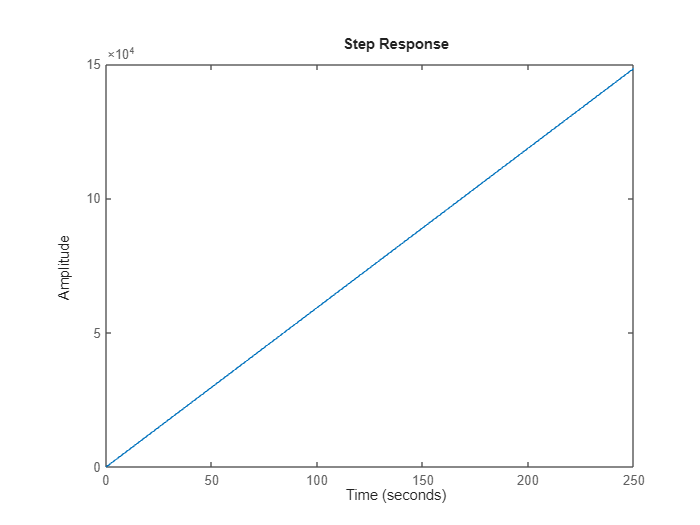

A = [-33.95 0; 360 0];
B = [55.99; 0];
C = [0 1];
plant_c = ss(A,B,C,0);
step(plant_c);

% Controlability verification
rank(ctrb(plant_c.A,plant_c.B))

ans = 2

## Discretization

Ts = 0.005;
plant_d = c2d(plant_c,Ts,'zoh');
pole(plant_d)

ans =     1.0000
    0.8439


## Internal Model

A_int_d = [1 Ts; 0 1];
B_int_d = [0; Ts];
A_aug_d = [plant_d.A zeros(2,2); -B_int_d*plant_d.C A_int_d];
B_aug_d = [plant_d.B; zeros(2,1)];
C_aug_d = [plant_d.C, zeros(1,2)];



# Control Design

#### Parameters

Overshoot [Mp] <= 25%, Velocity Error [Ev] = 0

## 1. Pole Placement + IMP 

% Pole selection in continuous
% Plant states poles
s1 = -40+50j;
s2 = -40-50j;
% Internal Model Poles
s3 = -70;
s4 = -80;
% Pole convertion e^(-Ts*s)
p = [exp(Ts*s1), exp(Ts*s2), exp(Ts*s3), exp(Ts*s4)]

p =    0.7933 + 0.2026i   0.7933 - 0.2026i   0.7047 + 0.0000i   0.6703 + 0.0000i


% K calculation
K = place(A_aug_d,B_aug_d,p);
A_cl = A_aug_d-B_aug_d*K;
sys_cl = ss(A_cl,B_aug_d,C_aug_d,0,Ts);
pole(sys_cl)

ans =    0.7933 + 0.2026i
   0.7933 - 0.2026i
   0.6703 + 0.0000i
   0.7047 + 0.0000i


step(syscl)

Not enough input arguments.

Error in syscl (line 12)
[a,b,c,d]=unpck(sys);

A=plant_ss_discrete.A
B=plant_ss_discrete.B
C=plant_ss_discrete.C




## 2. Pole Placement + IMP + Ludenberg estimator 

## *3. LQR + IMP*

## *4. LQG + IMP*